# Paderborn轴承故障数据集

## 1、实验平台

        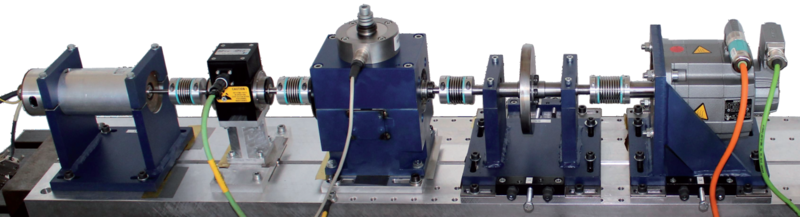

- 试验台由几个模块组成（从左到右依次为）：电动机、扭矩测量轴、滚动轴承测试模块、飞轮和负载电机，如上图所示。通过将不同损伤类型的滚珠轴承安装在轴承测试模块中，生成实验数据。

- 所有测试轴承型号均为6203型号滚动轴承。

## 2、试验说明

- **损伤的种类**

- 单点损伤（Single damage）：滚动轴承的单一组件受到单一损伤的影响，例如内圈上的一个点蚀坑。

- 重复性损伤（Repetitive damage）：相同的损伤症状在同一轴承部件的几个地方重复出现，例如内圈上有多个非连续的点蚀坑。

- 多次损伤（Multiple damage）：不同的破环症状发生在同一轴承的不同部件上，例如内圈和外圈的点蚀坑。

- **损伤的标准（对于重复性损伤和多次损伤而言）**

- 规律。损伤症状以一种规律的形式分布在部件上。

- 随机。损伤症状以一种随机的形式分布在部件上。

- 没有重复。破环仅发生一次，标准未被引用。

- **损伤程度**

            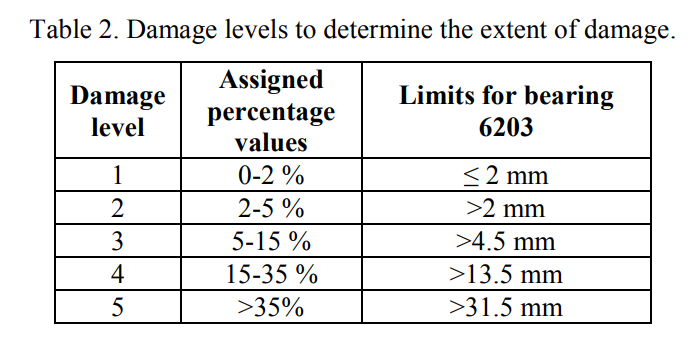

- **参数设置**

- 电机电流的采样频率为：64KHz

- 振动信号的采样频率为：64KHz

- 机械参数(加载力，加载力矩，速度)的采样频率:4KHz

- 温度的采样频率为：1Hz

- **试验工况条件**

            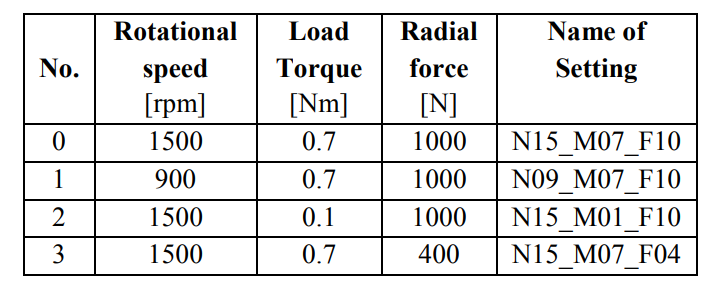

%工况选择
fs = 64000;
conditionlabel = 0;
switch conditionlabel
    case 0
        condition = 'N15_M07_F10';
    case 1
        condition = 'N09_M07_F10';
    case 2
        condition = 'N15_MO1_F10';
    case 3
        condition = 'N15_M07_F04';
end


## 3、数据集组成

    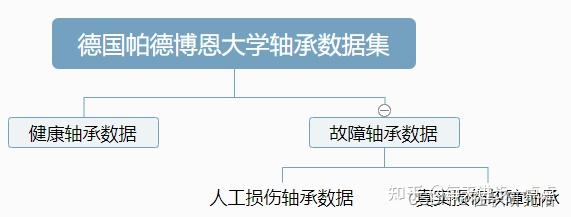

人工损伤轴承12个（外圈7个，内圈5个），加速寿命试验损伤轴承14个（外圈5个，内圈6个，内圈和外圈复合的2个）,健康轴承6个。

- **人工损伤轴承型号及其故障类型**

        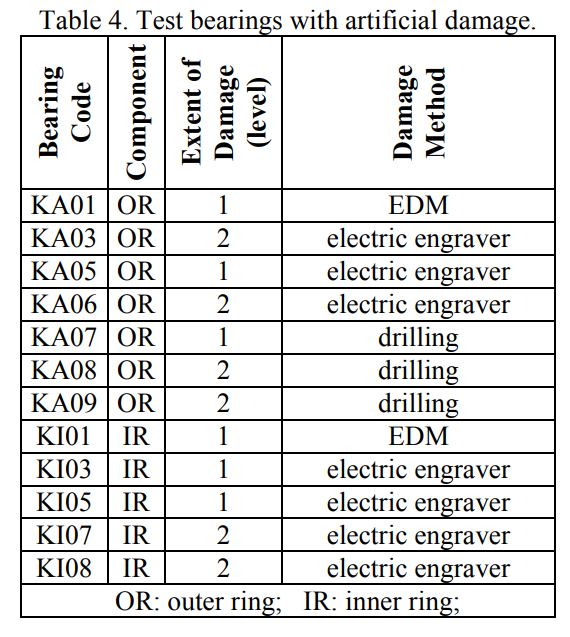

BearingType = 'KA08';
path = [BearingType '/' condition '_' BearingType];

- **加速寿命试验损伤的轴承型号及其故障类型**

        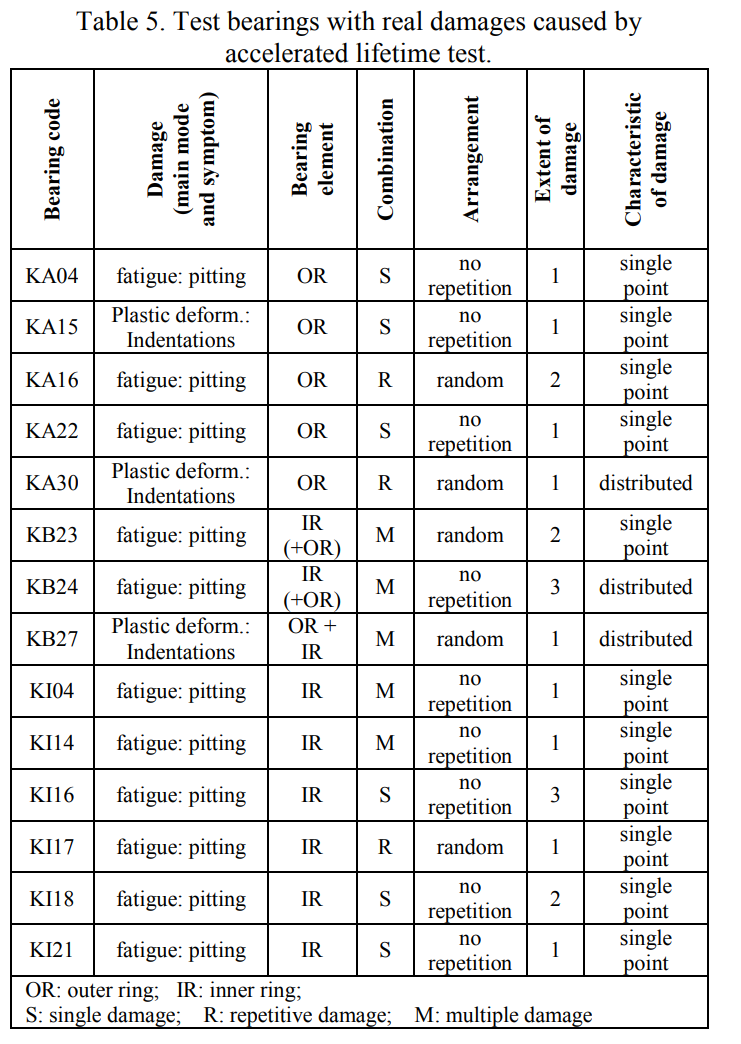

BearingType = 'KI18';
path2 = [BearingType '/' condition '_' BearingType];

- **健康轴承型号**

        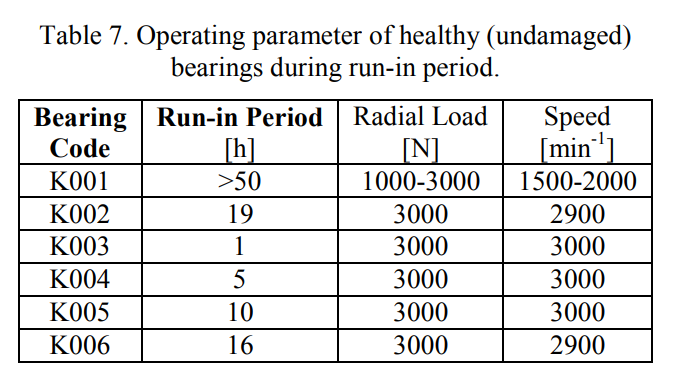

BearingType = 'K002';
path1 = [BearingType '/' condition '_' BearingType];

## 4、数据说明

- 每个轴承型号的文件夹下有4种工况的数据，每个工况的数据有20个，每个数据采集时间均为4秒。

- 每个mat文件里面，有info、x、y和Description四个数据集，其中所有数据均存储在Y这个结构体下。

- Y结构体包含了电机的电流数据（2个，大小为1X256823），温度数据（1个，大小1X4），机械参数（负载（force）、转速（speed）、扭矩（torque））和振动数据（1个，大小为1X256823）。

tic
fs = 64000;
L = fs/5;
%轴承型号
BT = {'KA01';'KA03';'KA05';'KA07';'KA08';'KA04';'KA16';'KA22';
               'KI01';'KI03';'KI05';'KI07';'KI08';'KI16';'KI17';'KI21';
               'K001';'K002';'K003';'K004';'K005';'K006'};
DT =  {'Outer Fault';'Outer Fault';'Outer Fault';'Outer Fault';'Outer Fault';'Outer Fault';'Outer Fault';'Outer Fault';
               'Inner Fault';'Inner Fault';'Inner Fault';'Inner Fault';'Inner Fault';'Inner Fault';'Inner Fault';'Inner Fault';
               'normal';'normal';'normal';'normal';'normal';'normal'};
K = 1;
CN_Promote = {};
EN_Promote = {};
Target = {};
signalmatrix = zeros(4*22*1*100,12818);
for conditionlabel = 0:3
    for bearing_idx = 1:22
        BearingType = BT{bearing_idx};
        for sample_idx = 1
            for sequence_idx = 1:100

                switch conditionlabel
                    case 0
                        condition = 'N15_M07_F10';
                        contition_label = [1500 0.7 1000];
                    case 1
                        condition = 'N09_M07_F10';
                        contition_label = [900 0.7 1000];
                    case 2
                        condition = 'N15_M01_F10';
                        contition_label = [1500 0.1 1000];
                    case 3
                        condition = 'N15_M07_F04';
                        contition_label = [1500 0.7 400];
                end
                testing_para = [64e3 L/fs];
                path1 = [BearingType '/' condition '_' BearingType];
                data1 = PardFileRead(path1,sample_idx,'Vib');
                Step = floor((length(data1)-L)/99);
                SelectedSceq = data1(Step*(sequence_idx-1)+1:Step*(sequence_idx-1)+L);
                
                [TimeHI,FreqHI]=HIComputation(SelectedSceq,fs);
                THI = TimeHI([1 2 3 5 6 9])';
                FHI = FreqHI([1 3 4 5 10 11])';
                HI = [THI FHI];
                Propmt = [HI contition_label testing_para];
                % CN_Description = CNDescription(TimeHI,FreqHI,conditionlabel,fs,L);
                % EN_Description = ENDescription(TimeHI,FreqHI,conditionlabel,fs,L);
                [Damage_Description,Damge_Type] = TargetDescription(BearingType,BT,DT);
                % CN_Promote{K} = CN_Description;
                % EN_Promote{K} = EN_Description;
                Target = Damge_Type;
                signalmatrix(K,:) = [SelectedSceq Propmt Target];
                K = K+1;
            end
        end
    end
end
toc
P_T = [CN_Promote;EN_Promote;Target];

csvwrite('PU_LLMDataset.csv',signalmatrix)

历时 173.612996 秒。


xlswrite('PULLMdataset_P_T.xlsx',P_T)

csvwrite('PULLMdataset.csv',signalmatrix)
xlswrite('PULLMdataset.csv',P_T,'A12801')


% data2 = filter(bhi,1,data2);
%轴承型号
for i = 1:3

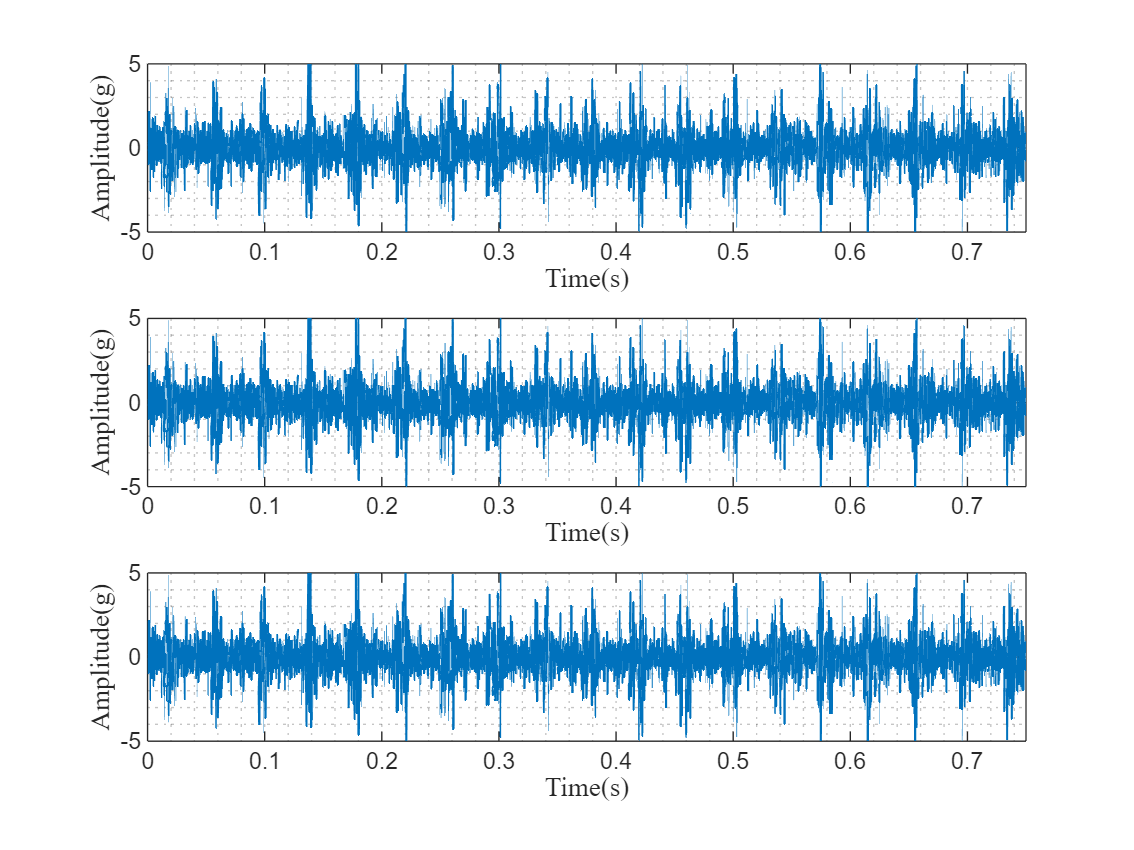

    Types = {'KA04','KI21','KB24'};
    BearingType = Types{i};
    
    path1 = [BearingType '/' condition '_' BearingType];
    
    data = PardFileRead(path1,1,'Vib');
    datas(i,:) = data(1:256000);
end

length = 64000*0.75;
pre = 4096;
t = length/fs;
figure
Datra = datas(1,pre+1:pre+length)*0.2+datas(3,pre+1:pre+length)*1.7;
for i = 1:3
    subplot(3,1,i)
    plot(linspace(0,t,length),Datra/2,LineWidth=0.9)
    xlim([0 t])
    grid off
    xlabel('Time(s)',fontname='Times New Roman',FontSize=10)
    ylabel('Amplitude(g)',fontname='Times New Roman',FontSize=10)
    hold on
    grid minor
    ylim([-10 10]/2)
end



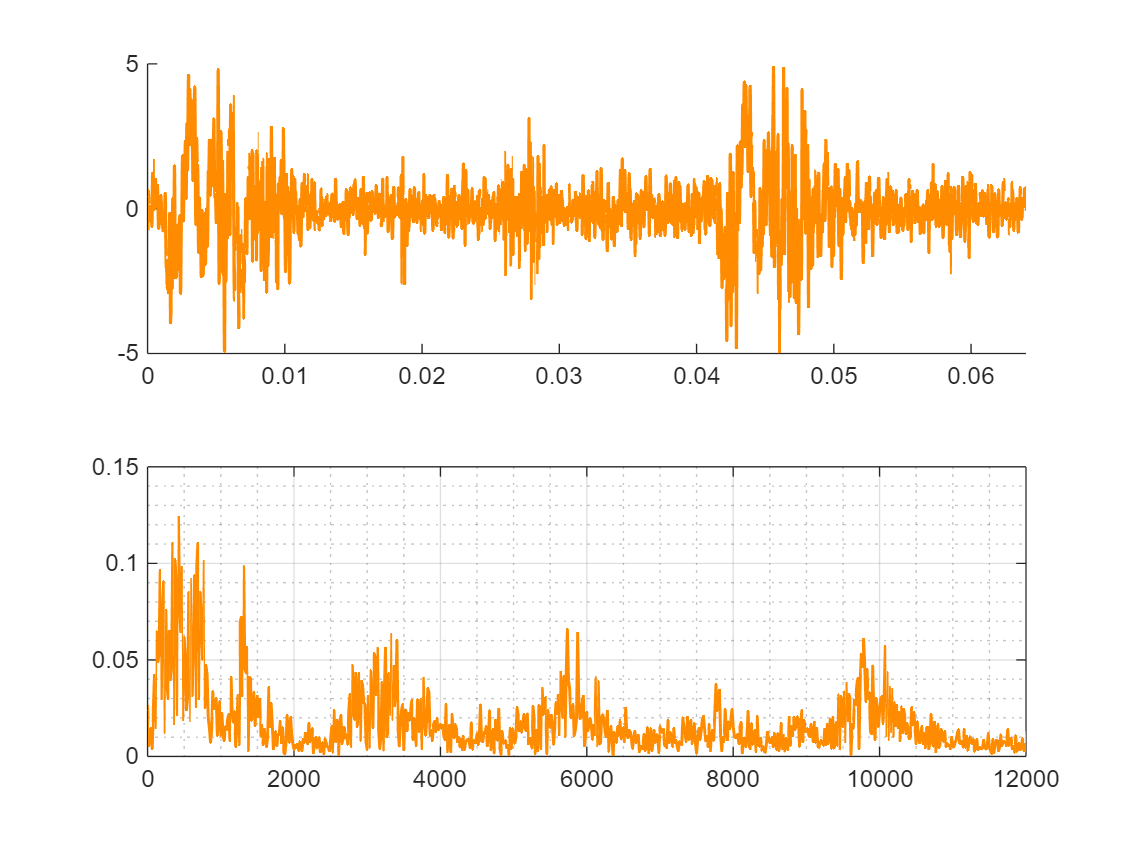

length = 4096;
pre = 7500;
t = length/fs;
figure
subplot(211)



hold on
plot(linspace(0,t,length),data(pre+1:pre+length),Color="#FF8C00",LineWidth=1.2)
xlim([0 t])
ylim([-5 5])
box off
grid on

set (gca,'gridcolor','w')
set (gca,'color','none')


% subplot(223)
subplot(212)

FFTplot(data(pre+1:pre+length),fs,"#FF8C00")
xlim([0 12000])
xlabel ' '
ylabel ' '
set (gca,'color','none')
ylim([0 0.15])
grid on
grid minor
box on

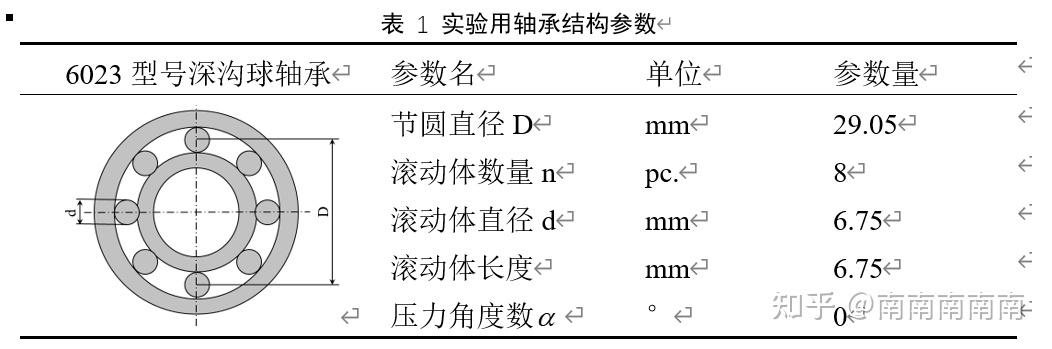

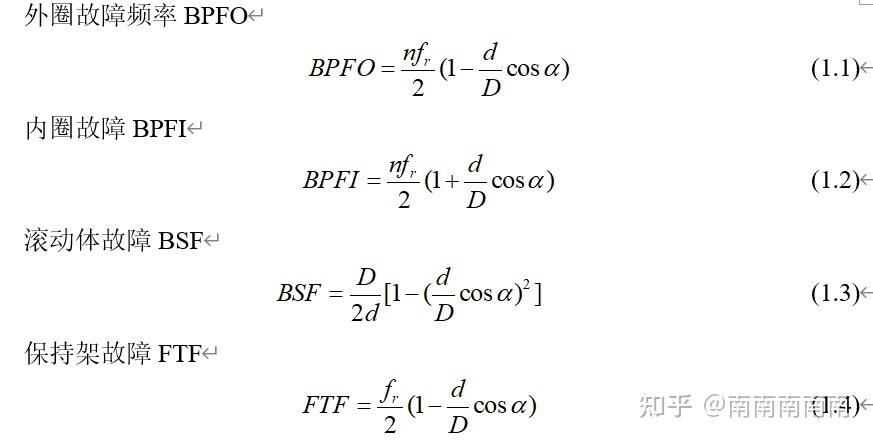

%轴承故障特征频率计算
D = 29.05;
d = 6.75;
n = 8;
fr = 1500/60;
BPFO = n*fr*(1-d/D)/2
BPFI = n*fr*(1+d/D)/2

%工况选择
fs = 64000;
conditionlabel = 3;    
switch conditionlabel
   case 0
       condition = 'N15_M07_F10';
   case 1
       condition = 'N09_M07_F10';
   case 2
       condition = 'N15_M01_F10';
   case 3
       condition = 'N15_M07_F04';
end
%轴承型号
for i = 1:5
    Types = {'K001','KA04','KA16','KI04','KI18'};
    BearingType = Types{i};
    
    path1 = [BearingType '/' condition '_' BearingType];
    
    data = PardFileRead(path1,1,'Vib');
    datas(i,:) = data(1:256000);
end

% data2 = filter(bhi,1,data2);

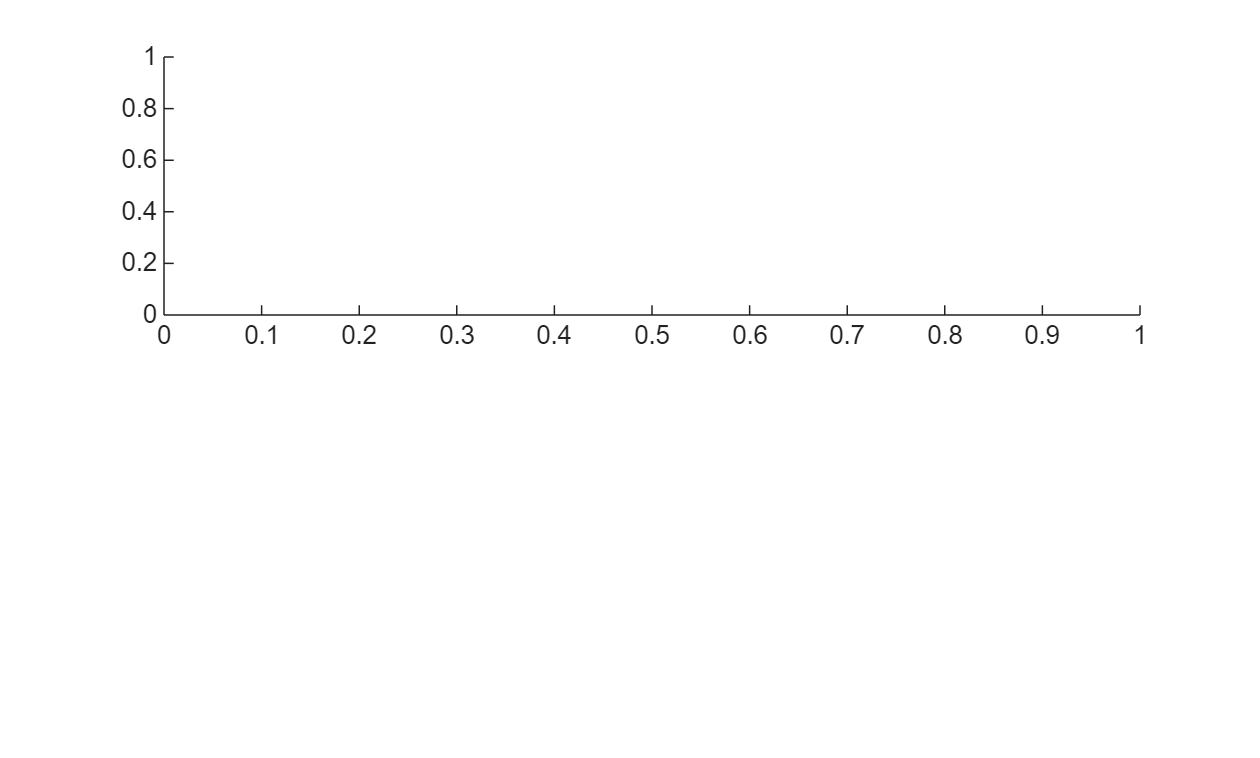

length = 4096;
pre = 7500;
t = length/fs;
figure
subplot(211)

plot(linspace(0,t,length),data1(pre+1:pre+length),Color="#0072BD",LineWidth=1.2)

函数或变量 'data1' 无法识别。

% xlim([0 length])
% ylim([-1.5 1.5])
% grid on
% subplot(222)
hold on
plot(linspace(0,t,length),data2(pre+1:pre+length),Color="#FF8C00",LineWidth=1.2)
xlim([0 t])
ylim([-2.5 2.5])
grid on
legend('KA04-real','KA04-generated')
xlabel('Time(s)',FontName='Times New Roman')
ylabel('Acceleration(g)',FontName='Times New Roman')

length = 4096;
pre = 1700;
t = length/fs;
figure
tiledlayout("vertical","Padding","compact");
for i = 1:4
    nexttile
    plot(linspace(0,t,length),datas(i,pre+1:pre+length),Color=	"#FF9933",LineWidth=1.2)
    xlim([0 t])
    xticklabels ''
    yticklabels ''
    xticks ''
    yticks ''
    box off
    axis off
    
end